## Import BIDS dataset

**Run 'eeglab' from the folder containing the eeglab codes. This will add all the relevant EEGLAB functions and directories to path.**

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is ~/eeg_options.m
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "ICLabel" v1.4 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.8 (see >> help eegplugin_clean_rawdata) - new version 2.7 available
EEGLAB: adding "dipfit" v5.0 (see >> help eegplugin_dipfit) - new version 4.3 available
EEGLAB: adding "firfilt" v2.6 (see >> help eegplugin_firfilt)


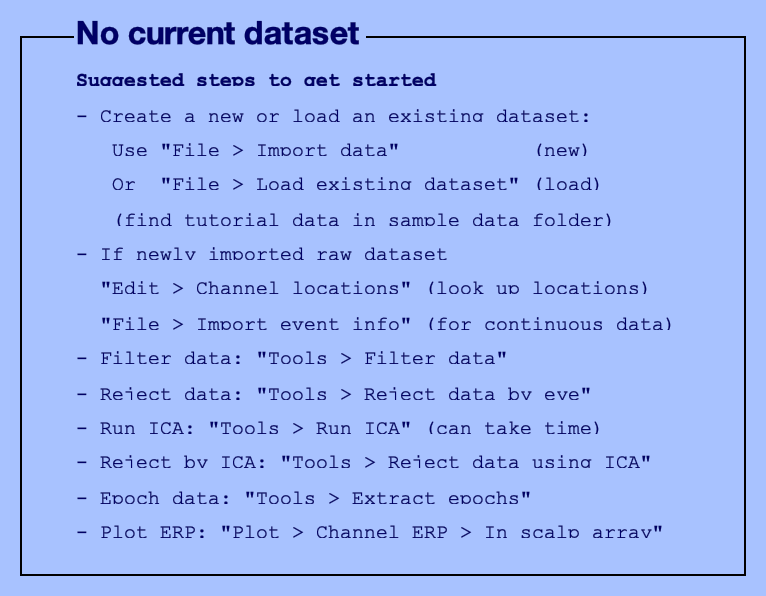

You are using the latest version of EEGLAB.


eeglab;

**Steps:**

- **Download the ds004186 dataset from openneuro using this Repository path  **[**https://github.com/OpenNeuroDatasets/ds004186.git**](https://github.com/OpenNeuroDatasets/ds004186.git)** and the steps mentioned here: **[**https://in.mathworks.com/help/matlab/matlab_prog/use-git-in-matlab.html**](https://in.mathworks.com/help/matlab/matlab_prog/use-git-in-matlab.html)

- **Add ds004186 and subfolders to path**

- **Make ds004186 current directory. **

- **Then run the following code:**

filepath = fileparts(which('participants.tsv')); % assumes if this BIDS file is present, it belongs to ds004186
if isempty(filepath)
    error('Cannot find ds004186 BIDS dataset, download it from OpenNeuro.org, uncompress it, and add it to your Matlab path')
end

The function pop_importbids() imports a BIDS format folder structure into an EEGLAB study. 

If 'bidsevent' is 'on' then events will be imported from the BIDS .tsv event file and events in the raw binary EEG files will be ignored. Similarly 'bidschanloc', 'on' will import channel locations from BIDS .tsv file and ignore any locations in raw EEG files. The 'studyName' field lets you specify the name of the newly created STUDY.

[STUDY, ALLEEG] = pop_importbids(filepath,'bidsevent','off','bidschanloc','off','studyName','Auditory_Oddball_Task');

## Process dataset

Loop across datasets and process data epochs. The type of epoch and any other interesting field is in epoch_type.datasetinfo.trialinfo; all fields in this structure will be saved as different columns. Pass a label filename which will be updated by mat2tiff_EEG.

CURRENTSTUDY = 1;
for CURRENTSET = 1:length(ALLEEG)
    CURRENTSET
    EEG =  ALLEEG(CURRENTSET);
    EEGepoch = pop_epoch(EEG, unique({EEG.event.type}), [-1 2]);
    label_info = mat2sample(EEGepoch,'HBN_EOEC_labels_s3.txt','s3://openneuro.org/ds004186')
end
